# Lab 3: Fourier Transform

**1.  **Consider the rectangular pulse function with parameter `a`:


$$\text{rect}(at) = \left\{ 
\begin{array}{rl} 
1, & |t| < a/2  
\\
0.5, & |t| = a/2  
\\
0, & |t| > a/2  
\end{array} \right.$$


Define the symbolic rectangular pulse function in terms of the symbolic variable `t` and numeric value `a` defined in the space below. Name the result `r`.

**Hint**: use the [`rectangularPulse`](https://www.mathworks.com/help/symbolic/rectangularpulse.html) function.

% Use these
a = 2;
syms t

% Define r here
r = rectangularPulse(-a,a,t)

$$r = \mathrm{rectangularPulse}\left(-2,2,t\right)$$

**2.  **Plot the rectangular pulse `r` using [`fplot`](https://www.mathworks.com/help/matlab/ref/fplot.html).

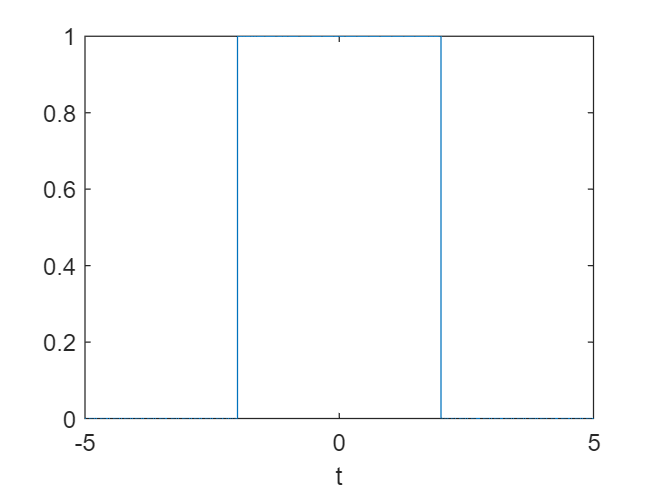

% Write your code here
fplot(r)
xlabel("t")

**3.** (optional) Compute the Fourier transform of $\text{rect}(at)$ by hand.

**4. **Use the Symbolic Math Toolbox to compute the Fourier transform of `r` defined in Q1 using [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html). Store the result in `rhat`.

% Compute the Fourier transform here
rhat = fourier(r)

$$rhat = \frac{\sin\left(2\,w\right)+\cos\left(2\,w\right)\,\mathrm{i}}{w}-\frac{-\sin\left(2\,w\right)+\cos\left(2\,w\right)\,\mathrm{i}}{w}$$

**5. **Simplify `rhat` using the [`simplify`](https://www.mathworks.com/help/symbolic/simplify.html) function. Save the result in `rhat`.

rhat = simplify(rhat)

$$rhat = \frac{2\,\sin\left(2\,w\right)}{w}$$

**6. **Plot the Fourier transform using [`fplot`](https://www.mathworks.com/help/matlab/ref/fplot.html) on the interval `[-100,100]`. 

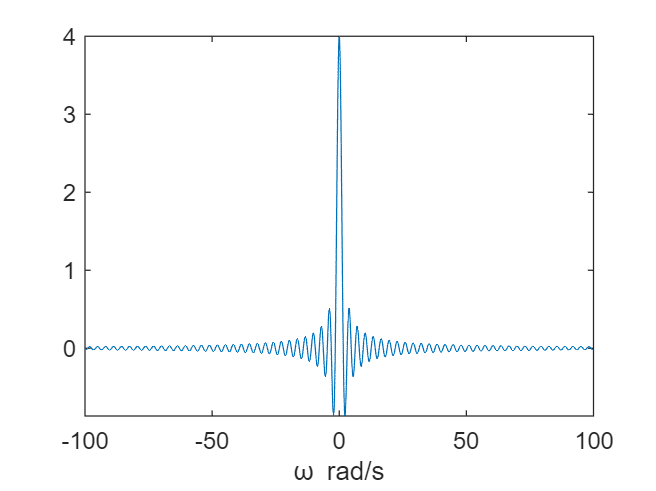

fplot(rhat,[-100,100])
xlabel("\omega rad/s")

**7. **Define and plot a function $y$ that has a carrier cosine wave modulated by a rectangular pulse:


$$y(t) = \text{rect}(at)\cos(2 \pi f  t)$$


Use the symbolic variable `t` and the values `a` and `f`. Plot y using [`fplot`](https://www.mathworks.com/help/matlab/ref/fplot.html).

% Use these
a = 2;
f = 5;
syms t

% Define f here
y = rectangularPulse(-a,a,t)*cos(2*pi*f*t)

$$y = \cos\left(10\,\pi \,t\right)\,\mathrm{rectangularPulse}\left(-5,5,t\right)$$

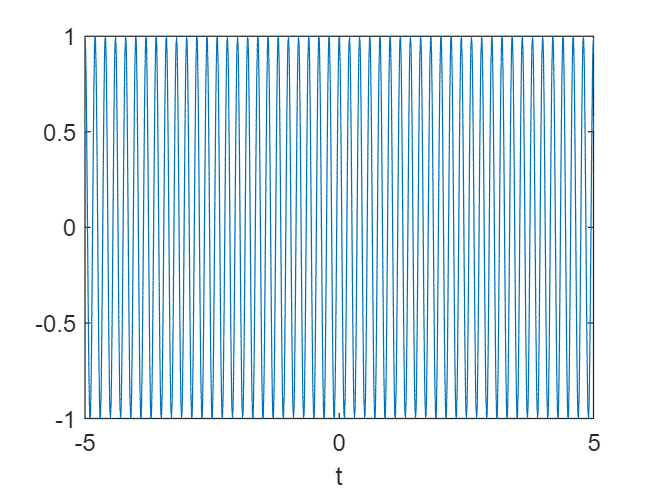

% Plot f here
fplot(y)
xlabel("t")

**8. **(optional) Compute the Fourier transform of $y(t)$ by hand.

**Hint**: rewrite the cosine function in terms of complex exponentials.

**9. **Use the Symbolic Math Toolbox to compute, simplify, and plot the Fourier transform of `y` defined in part **7**. Store the result in `yhat`. Plot on the interval  `[-100,100]`. 

% Write your code here
yhat = simplify(fourier(y))

$$yhat = -\frac{2\,w\,\sin\left(5\,w\right)}{100\,\pi^{2}-w^{2}}$$

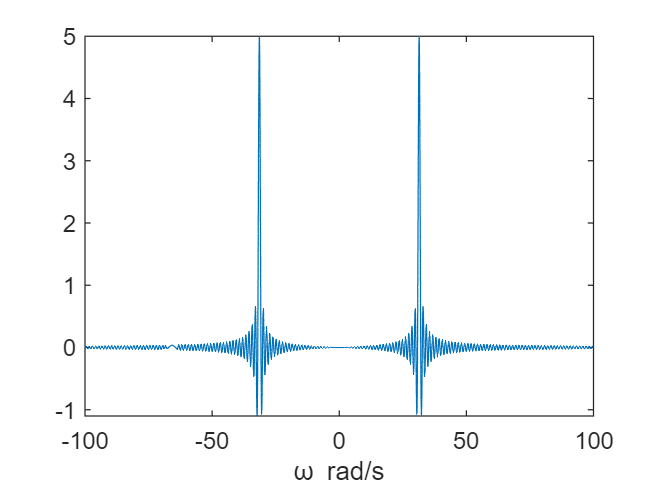

fplot(yhat,[-100,100])
xlabel("\omega rad/s")

**10. **Change the carrier frequency to 10 Hz in part **7** and then rerun your code from parts **7** and **9**. How does the Fourier transform $\hat{f}$ change? 

% Write your answer here in quotes
Q9ans = "The sinc function shifts to +- 20*pi rad/s"

Q9ans = "The sinc function shifts to +- 20*pi rad/s"

**11. **Increase the width of the rectangular pulse (by increasing the value of `a`). How does the frequency content change?

Q10ans = "The frequency content becomes more localized."

Q10ans = "The frequency content becomes more localized."